## Questão 1

a) 2-PAM (BPSK)

A constelação do 2-PAM consiste de apenas dois símbolos, que chamaremos de s0 e s1. Cada símbolo terá um valor, que é representado no eixo dos números reais.

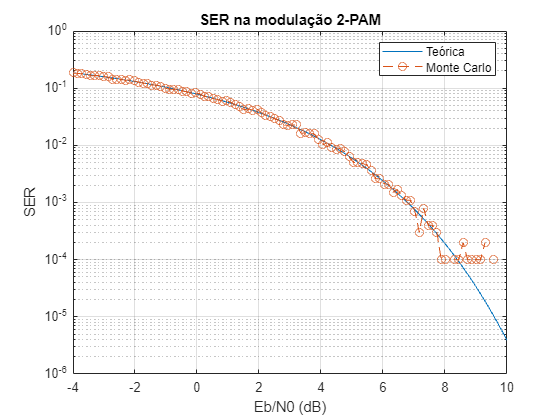

% seed
rng('default')
eb_n0_dB = linspace(-4,10,100);
eb_n0 = 10.^(eb_n0_dB./10);
[~,Pe_teorica] = berawgn(eb_n0_dB, 'pam', 2);
Pe_montecarlo = pam_2(eb_n0);

figure;
semilogy(eb_n0_dB, Pe_teorica)
hold on
semilogy(eb_n0_dB, Pe_montecarlo, 'LineStyle', '--', 'Marker', 'o')

xlabel('Eb/N0 (dB)')
ylabel('SER')
legend('Teórica','Monte Carlo')
title('SER na modulação 2-PAM')
grid on
hold off

b) 4-PAM

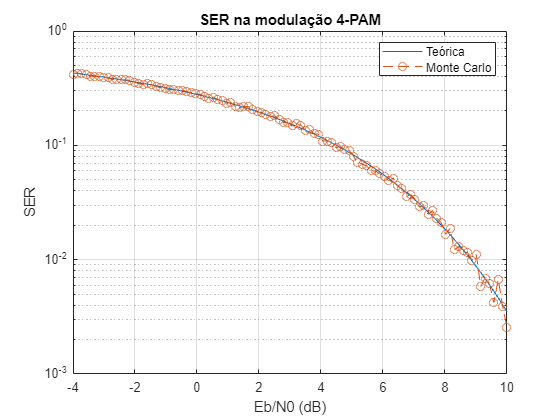

[~,Pe_teorica] = berawgn(eb_n0_dB, 'pam', 4);
Pe_montecarlo = pam_4(eb_n0);

figure;
semilogy(eb_n0_dB, Pe_teorica)
hold on
semilogy(eb_n0_dB, Pe_montecarlo, 'LineStyle', '--', 'Marker', 'o')

xlabel('Eb/N0 (dB)')
ylabel('SER')
legend('Teórica','Monte Carlo')
title('SER na modulação 4-PAM')
grid on
hold off

c) 4-QAM (QPSK)

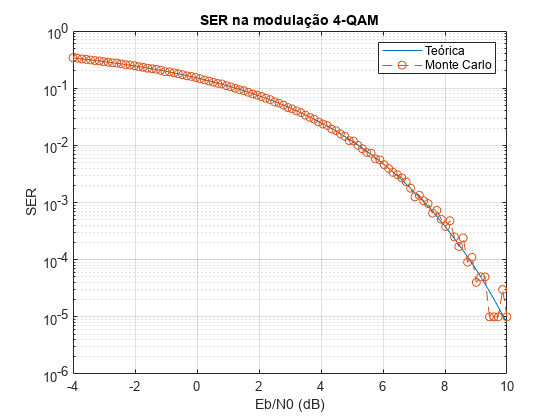

[~,Pe_teorica] = berawgn(eb_n0_dB, 'qam', 4);
Pe_montecarlo = qam_4(eb_n0);

figure;
semilogy(eb_n0_dB, Pe_teorica)
hold on
semilogy(eb_n0_dB, Pe_montecarlo, 'LineStyle', '--', 'Marker', 'o')

xlabel('Eb/N0 (dB)')
ylabel('SER')
legend('Teórica','Monte Carlo')
title('SER na modulação 4-QAM')
grid on
hold off

d) 2-FSK

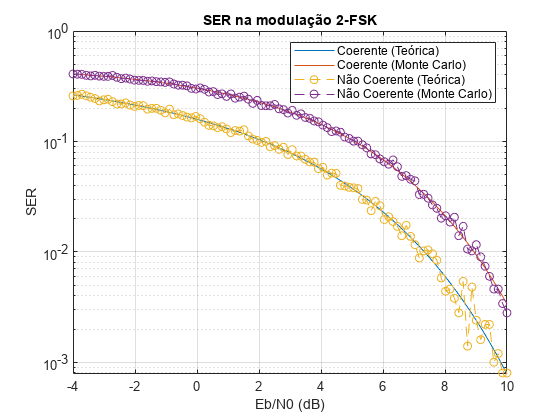

[~,Pe_teoricaCoerente] = berawgn(eb_n0_dB, 'fsk', 2, 'coherent');
[~,Pe_teoricaNaoCoerente] = berawgn(eb_n0_dB, 'fsk', 2, 'noncoherent');
[Pe_montecarlo_coerente, Pe_montecarlo_nao_coerente] = fsk_2(eb_n0);

figure;
semilogy(eb_n0_dB, Pe_teoricaCoerente)
hold on
semilogy(eb_n0_dB, Pe_teoricaNaoCoerente)
semilogy(eb_n0_dB, Pe_montecarlo_coerente, 'LineStyle', '--', 'Marker', 'o')
semilogy(eb_n0_dB, Pe_montecarlo_nao_coerente, 'LineStyle', '--', 'Marker', 'o')

xlabel('Eb/N0 (dB)')
ylabel('SER')
legend('Coerente (Teórica)','Coerente (Monte Carlo)', 'Não Coerente (Teórica)','Não Coerente (Monte Carlo)')
title('SER na modulação 2-FSK')
grid on
hold off